# question 3

## (a)

clc; clear;
disp("(a)")

(a)


syms n x L a cn t 

u(x,t) = cn * sin(n*sym(pi)*x / L) * exp(-(a^2 * n^2 * sym(pi)^2 * t)/L^2);
ut = diff(u(x,t), t);
uxx = diff(diff(u(x,t), x), x);

disp("Ut = ")

Ut = 


disp(ut)

$$-\frac{a^{2}\,\mathrm{cn}\,n^{2}\,\pi^{2}\,{\mathrm{e}}^{-\frac{a^{2}\,n^{2}\,t\,\pi^{2}}{L^{2}}}\,\sin\left(\frac{\pi \,n\,x}{L}\right)}{L^{2}}$$

disp("Uxx = ")

Uxx = 


disp(uxx)

$$-\frac{\mathrm{cn}\,n^{2}\,\pi^{2}\,{\mathrm{e}}^{-\frac{a^{2}\,n^{2}\,t\,\pi^{2}}{L^{2}}}\,\sin\left(\frac{\pi \,n\,x}{L}\right)}{L^{2}}$$


if ut == a^2 * uxx
    disp("Heat Eqn is satisfied")
end

Heat Eqn is satisfied


## (b)

fprintf("\n(b)\n")


(b)


clc; clear;
syms n x L f(x)

f(x) = 10;
cn = (2 / L) * int(f(x) * sin(n*pi*x / L), x, 0, L);

disp("value of cn is ")

value of cn is 


disp(cn)

$$\frac{40\,{\sin\left(\frac{\pi \,n}{2}\right)}^{2}}{n\,\pi }$$

## (c)

fprintf("\n(c)\n")


(c)


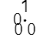

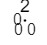

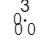

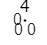

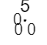

L = pi; a = sqrt(1.71);
syms n x t 
u(x,t,n) = cn * sin(n*pi*x / L) * exp(-(a^2 * n^2 * pi^2 * t)/L^2);
x = linspace(0, pi, 60);
t = linspace(0, 6, 50);
[X,T] = meshgrid(x,t);
arr = zeros(length(t),length(x));

for n = 1:5
    arr = arr + eval(u(X,T,n));
    figure;
    surf(X, T, arr)
    title("n = ", n)
    xlabel("x")
    ylabel("t")
    zlabel("U(x,t)")
end

## (d)

fprintf("\n(d)\n")


(d)


surf(X, T, arr)
title("n = ", n)
xlabel("x")
ylabel("t")
zlabel("U(x,t)")

## (e)

fprintf("\n(e)\n")


(e)


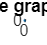

plot(t, eval(u(pi/2, t, 1)))
title("Temperature vs Time graph at midpoint of rod")
xlabel("t")
ylabel("U")